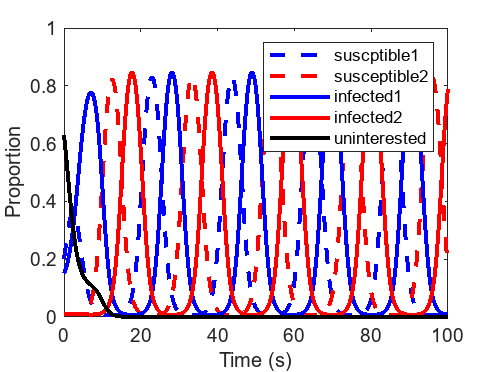

t0 = 0;
tfinal = 100;
p0 = [0.2; 0.01; 0.15; 0.01; 0.63];
u1 = zeros(1,50);
u2 = zeros(1,50);
b1 = 0.8*ones(1,50);
b2 = 0.8*ones(1,50);
a1 = 1*ones(1,50);
a2 = [zeros(1,3) 1*ones(1,47)];
m12 = [zeros(1,3) 0.2*ones(1,47)];
m21 = [zeros(1,3) 0.2*ones(1,47)];
d1 = 1*ones(1,50);
d2 = [zeros(1,3) 1*ones(1,47)];
l12 = [zeros(1,3) 1*ones(1,47)];
l21 = [zeros(1,3) 1*ones(1,47)];

ft = linspace(0, 100, 50);
[T, P] = ode45(@(t, p) ODEsys(t, p, ft, u1, u2, b1, b2, a1, a2, m12, m21, d1, d2, l12, l21), [t0 tfinal], p0);
plot(T, P(:,1),"b--",T, P(:,2),"r--",T, P(:,3),"b-",T, P(:,4),"r-", T, P(:,5),"k-",'LineWidth',2)

legend('suscptible1', 'susceptible2', 'infected1', 'infected2', 'uninterested')
xlabel("Time (s)")
ylabel("Proportion")

[M1, I1] = max(P(:,1))

M1 = 0.8312

I1 = 136

T(I1)

ans = 43.7301

[M2, I2] = max(P(:,2))                                                     

M2 = 0.8312

I2 = 238

T(I2)

ans = 74.9965

[M3, I3] = max(P(:,3))                                                     

M3 = 0.8468

I3 = 85

T(I3)

ans = 28.1363

[M4, I4] = max(P(:,4))                                                     

M4 = 0.8466

I4 = 118

T(101)

ans = 33.1606

int1 = P(:,5) - P(:,3)

int1 =     0.4800
    0.4634
    0.4461
    0.4283
    0.4100
    0.3105
    0.2012
    0.0861
   -0.0313
   -0.1142


T(8)

ans = 1.9886

T(9)

ans = 2.5119

int2 = P(:,5) - P(:,3)

int2 =     0.4800
    0.4634
    0.4461
    0.4283
    0.4100
    0.3105
    0.2012
    0.0861
   -0.0313
   -0.1142


T(8)

ans = 1.9886

P(9,3)

ans = 0.3235

T(255)

ans = 80.3110